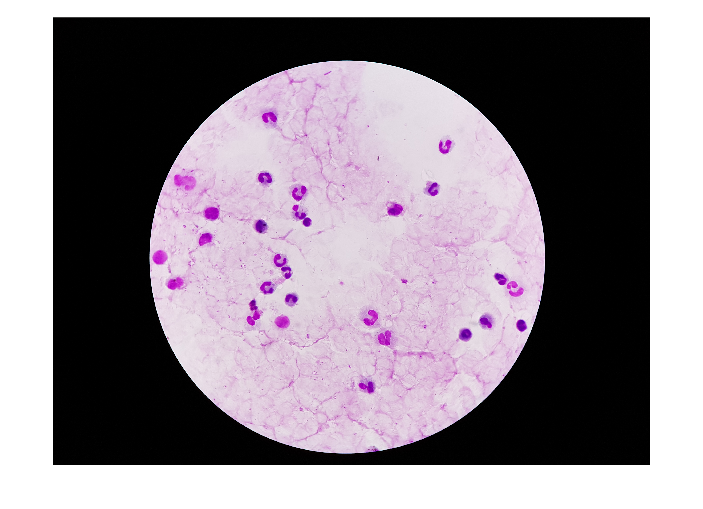

% --- Variables necesarias definidas previamente ---
IPF = imread('20170829_174225.jpg'); 
imshow(IPF)

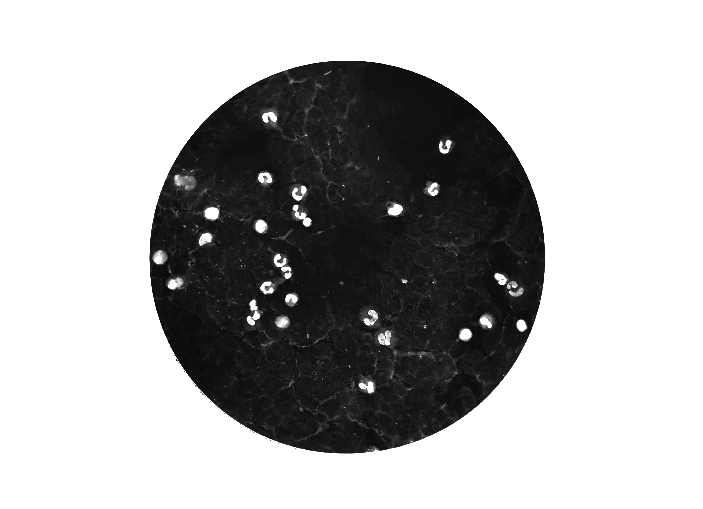

Imagen_FILT = im2double(IPF);    
I_gray = rgb2gray(Imagen_FILT);    
I_gray_uint8 = im2uint8(I_gray);     

% Máscara del portaobjetos (campo de visión)
Imagen_mascara_gray = rgb2gray(cat(3, IPF(:,:,1), IPF(:,:,2), zeros(size(IPF(:,:,1)))));
fov_mask = segmentCellsStainBased(Imagen_mascara_gray); 

% Canal 3 (núcleo) de imagen deconvolucionada
OD = -log(Imagen_FILT + 0.01);
OD = reshape(OD, [], 3);
W_manual = [
    0.650, 0.072, 0.707; 
    0.704, 0.990, 0.707; 
    0.286, 0.117, 0.000
];
W = W_manual ./ vecnorm(W_manual, 2, 2);
W = W';
C = OD * inv(W);
deconvolved_manual = reshape(C, size(IPF));
Imagen_nucleos = deconvolved_manual(:,:,3);
imshow(Imagen_nucleos)


% Aplicación de fov_mask y binarización de núcleos
bw = imbinarize(Imagen_nucleos);
Imagen_masked = bw .* fov_mask;

% Datos de parásitos reales
fileID = fopen('20170829_174225.txt', 'r');
lines = textscan(fileID, '%s', 'Delimiter', '\n'); fclose(fileID); lines = lines{1};
lines(1) = [];
data = cell(length(lines), 7); x2 = NaN(length(lines), 1); y2 = NaN(length(lines), 1);
for i = 1:length(lines)
    tokens = strsplit(lines{i}, ',');
    for j = 1:7
        if j <= length(tokens)
            data{i, j} = tokens{j};
        else
            data{i, j} = '';
        end
    end
end
dataTable = cell2table(data, 'VariableNames', {'ID','Label','Comment','Shape','NumPoints','X1','Y1'});
dataTable.X1 = str2double(dataTable.X1); dataTable.Y1 = str2double(dataTable.Y1);
solo_parasitos = dataTable(ismember(dataTable.Label, {'Parasite', 'Parasitized'}), :);

## **SEGMENTACIÓN BASADO EN GLOBAL THRESHOLDING**

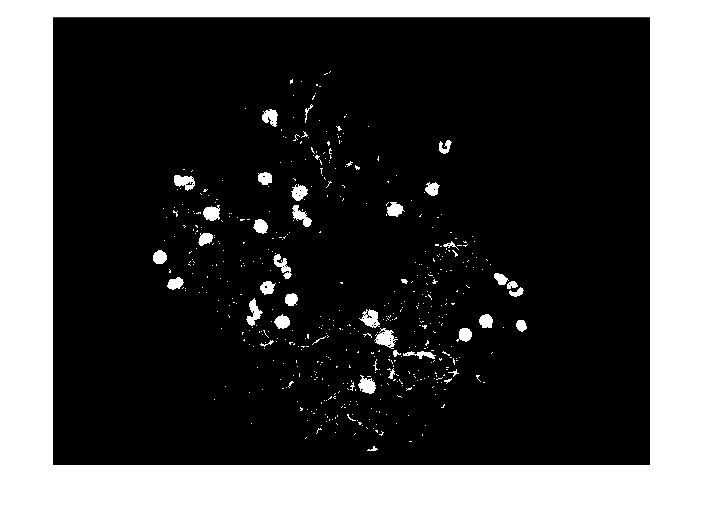

imagenEcualizada = adapthisteq(I_gray);

% Máscara circular del portaobjetos
mascaraPortaobjetos = imbinarize(imagenEcualizada, graythresh(imagenEcualizada));
mascaraPortaobjetos = imfill(mascaraPortaobjetos, 'holes');
mascaraPortaobjetos = bwareafilt(mascaraPortaobjetos, 1); 
imagenEcualizada(~mascaraPortaobjetos) = 0;  

% Umbral adaptativo para segmentar regiones oscuras (posibles glóbulos blancos)
pixelesDentroFOV = imagenEcualizada(fov_mask);  
umbralOscuridad = prctile(pixelesDentroFOV, 5);  
mascaraOscuros = imagenEcualizada < umbralOscuridad;
mascaraOscuros = mascaraOscuros & logical(fov_mask); 
imshow(mascaraOscuros)

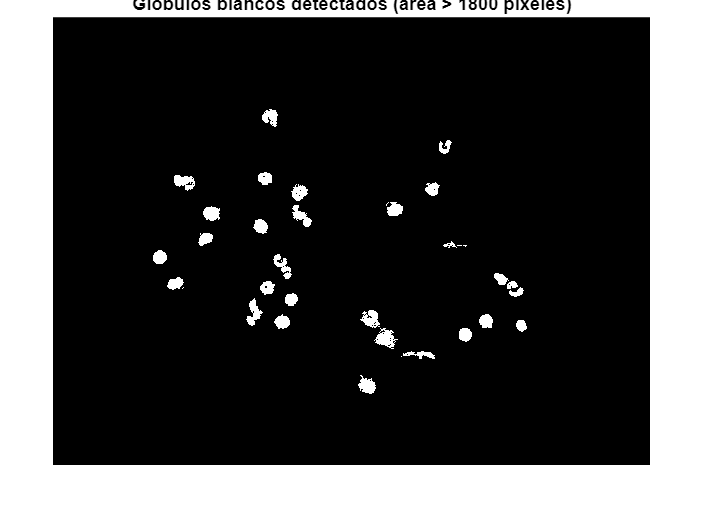


% Filtrar objetos por tamaño mínimo
areaMinimaGlobulos = 1800;
mascaraGlobulosBlancos = bwareafilt(mascaraOscuros, [areaMinimaGlobulos Inf]);

% Visualizar máscara de glóbulos blancos 
figure;
imshow(mascaraGlobulosBlancos);
title(['Glóbulos blancos detectados (área > ', num2str(areaMinimaGlobulos), ' píxeles)']);

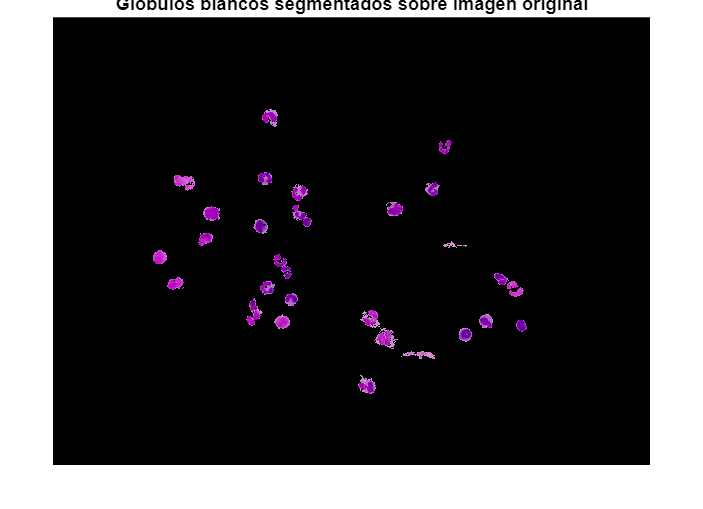


% Extraer glóbulos blancos sobre imagen original
mascaraRGB = repmat(mascaraGlobulosBlancos, 1, 1, 3);
imagenSoloGlobulos = Imagen_FILT;
imagenSoloGlobulos(~mascaraRGB) = 0;  
imagenSoloGlobulos = imagenSoloGlobulos .* fov_mask;

figure;
imshow(imagenSoloGlobulos);
title('Glóbulos blancos segmentados sobre imagen original');

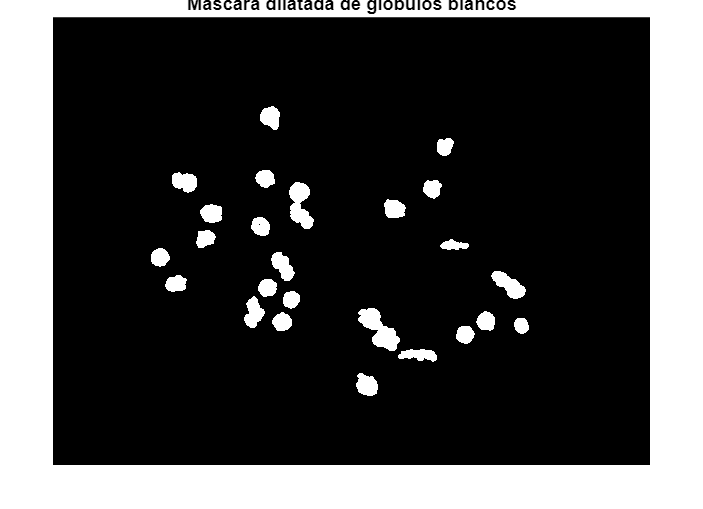


% Preparar imagen para segmentación global de parásitos
if size(imagenSoloGlobulos,3) == 3
    imagenGlobulosGris = rgb2gray(imagenSoloGlobulos);
else
    imagenGlobulosGris = imagenSoloGlobulos;
end

imagenGlobulosBinaria = imbinarize(imagenGlobulosGris);

% Dilatar máscara binaria de glóbulos para eliminar área cercana
elementoEstructurante = strel('disk', 15);
mascaraGlobulosDilatada = imdilate(imagenGlobulosBinaria, elementoEstructurante);

figure;
imshow(mascaraGlobulosDilatada);
title('Máscara dilatada de glóbulos blancos');

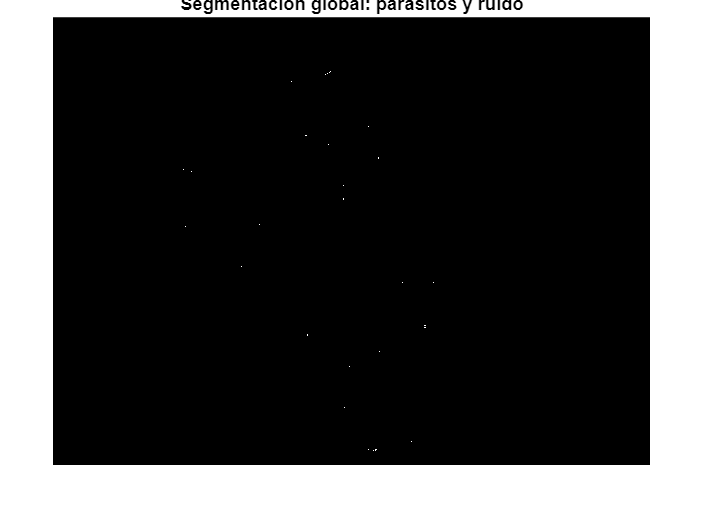


% Eliminar glóbulos blancos dilatados de imagen para segmentar parásitos
imagenSinGlobulos = Imagen_masked;
imagenSinGlobulos(mascaraGlobulosDilatada) = 0;
imagenSegmentable = uint8(imagenSinGlobulos);

% Segmentación global por umbral automático
umbralGlobal = graythresh(imagenSegmentable);
mascaraParasitoseRuido = imbinarize(imagenSegmentable, umbralGlobal);

% Filtrar objetos pequeños (ruido)
areaMinimaParasitos = 400;
mascaraParasitoseRuidoFiltrada = filtrar_por_tamano(mascaraParasitoseRuido, areaMinimaParasitos);

figure;
imshow(mascaraParasitoseRuidoFiltrada);
title('Segmentación global: parásitos y ruido');


% Detectar parásitos circulares
[centrosParasitos, radiosParasitos] = imfindcircles(mascaraParasitoseRuido, [2 5], 'Sensitivity', 0.92, 'EdgeThreshold', 0.5);

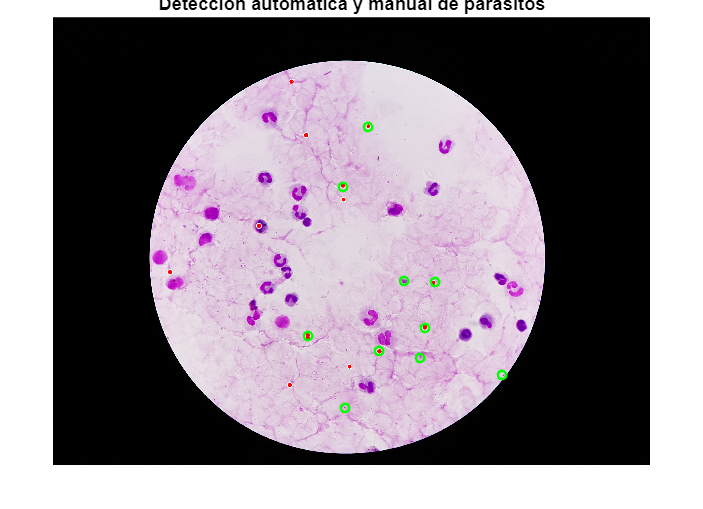


% Contar detecciones automáticas y reales
numDetectadosAuto = size(centrosParasitos, 1);
numParasitosReales = size(solo_parasitos, 1);
numTotalParasitos = numDetectadosAuto + numParasitosReales;

figure; imshow(IPF);
title('Detección automática y manual de parásitos');
hold on;

viscircles(centrosParasitos, radiosParasitos, 'EdgeColor', 'r'); 
plot(solo_parasitos{:,6}, solo_parasitos{:,7}, 'go', 'MarkerSize', 5, 'LineWidth', 1.5); 

hold off;


fprintf('Parásitos detectados automáticamente: %d\nParásitos reales anotados: %d\nTotal parásitos: %d\n', ...
    numDetectadosAuto, numParasitosReales, numTotalParasitos);

Parásitos detectados automáticamente: 15
Parásitos reales anotados: 10
Total parásitos: 25



% Validar detecciones automáticas contra parásitos reales
radioExtra = 20;
aciertosDeteccion = 0;

for i = 1:numParasitosReales
    puntoReal = [solo_parasitos{i,6}, solo_parasitos{i,7}];
    for j = 1:numDetectadosAuto
        centroDet = centrosParasitos(j,:);
        radioDet = radiosParasitos(j) + radioExtra;
        distancia = norm(puntoReal - centroDet);
        if distancia <= radioDet
            aciertosDeteccion = aciertosDeteccion + 1;
            break;
        end
    end
end

falsosPositivos = numDetectadosAuto - aciertosDeteccion;
falsosNegativos = numParasitosReales - aciertosDeteccion;

fprintf('Parásitos correctamente detectados: %d de %d reales\n', aciertosDeteccion, numParasitosReales);

Parásitos correctamente detectados: 6 de 10 reales


fprintf('Falsos positivos: %d\n', falsosPositivos);

Falsos positivos: 9


fprintf('Falsos positivos: %d\n', falsosNegativos);

Falsos positivos: 4


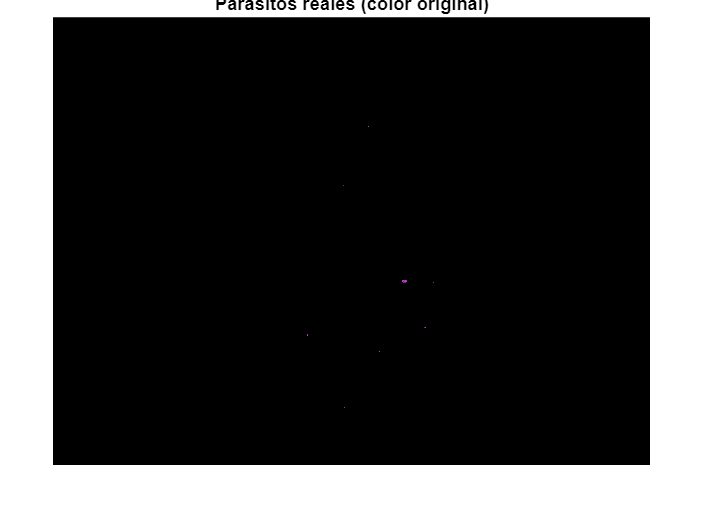


% Asociar objetos segmentados a parásitos reales
x_real = solo_parasitos{:,6};
y_real = solo_parasitos{:,7};
propsObjetos = regionprops(mascaraParasitoseRuido, 'Centroid', 'Area', 'Perimeter', 'PixelIdxList');
indicesObjetosAsignados = zeros(length(x_real), 1);

for i = 1:length(x_real)
    centroides = reshape([propsObjetos.Centroid], 2, [])';
    distancias = sqrt((centroides(:,1) - x_real(i)).^2 + (centroides(:,2) - y_real(i)).^2);
    [~, idxMin] = min(distancias);
    indicesObjetosAsignados(i) = idxMin;
end

% Extraer canales RGB e intensidades medias de parásitos reales 
R = IPF(:,:,1); G = IPF(:,:,2); B = IPF(:,:,3);
intensidadR = zeros(length(x_real),1);
intensidadG = zeros(length(x_real),1);
intensidadB = zeros(length(x_real),1);

mascaraParasitosFinal = false(size(mascaraParasitoseRuido));

areasParasitos = zeros(length(x_real), 1);
circularidadParasitos = zeros(length(x_real), 1);

for i = 1:length(indicesObjetosAsignados)
    idx = indicesObjetosAsignados(i);
    objeto = propsObjetos(idx);
    areasParasitos(i) = objeto.Area;
    if objeto.Perimeter > 0
        circularidadParasitos(i) = 4 * pi * objeto.Area / (objeto.Perimeter^2);
    else
        circularidadParasitos(i) = NaN;
    end

    mascaraParasitosFinal(objeto.PixelIdxList) = true;
    intensidadR(i) = mean(R(objeto.PixelIdxList));
    intensidadG(i) = mean(G(objeto.PixelIdxList));
    intensidadB(i) = mean(B(objeto.PixelIdxList));
end

% Visualizar parásitos reales sobre imagen original (color)
imagenParasitosColor = zeros(size(IPF), 'like', IPF);
for canal = 1:3
    tempCanal = IPF(:,:,canal);
    tempCanal(~mascaraParasitosFinal) = 0;
    imagenParasitosColor(:,:,canal) = tempCanal;
end

figure;
imshow(imagenParasitosColor);
title('Parásitos reales (color original)');

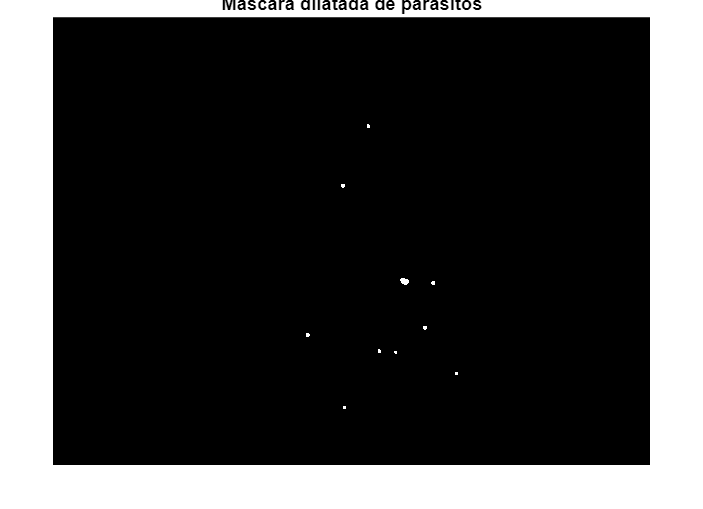


% Dilatar máscara binaria de parásitos reales
parasitosGris = rgb2gray(imagenParasitosColor);
mascaraBinariaParasitos = parasitosGris > 0;

elementoEstructuranteDil = strel('disk', 10);
mascaraParasitosDil = imdilate(mascaraBinariaParasitos, elementoEstructuranteDil);

figure;
imshow(mascaraParasitosDil);
title('Máscara dilatada de parásitos');

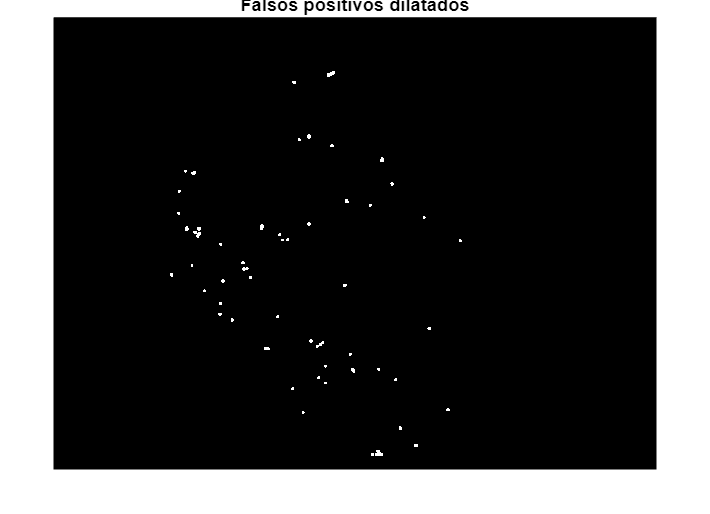


% Detectar falsos positivos
mascaraParasitosInvertida = ~mascaraParasitosDil;
falsosPositivosMask = mascaraParasitoseRuido & mascaraParasitosInvertida;
falsosPositivosMask = imdilate(falsosPositivosMask, elementoEstructuranteDil);

figure;
imshow(falsosPositivosMask);
title('Falsos positivos dilatados');

function fov_mask  = segmentCellsStainBased(I)

    if size(I, 3) == 3
        I = rgb2gray(I);
    end

    level = graythresh(I);
    bw = imbinarize(I, level);

    if mean(I(bw)) < mean(I(~bw))
        bw = ~bw;
    end

    bw_clean = imopen(bw, strel('disk', 5));
    bw_clean = imclose(bw_clean, strel('disk', 5));
    bw_clean = imfill(bw_clean, 'holes');

    stats = regionprops(bw_clean, 'Area', 'Centroid', 'EquivDiameter');

    [~, idx] = max([stats.Area]);
    circle_centroid = stats(idx).Centroid;
    circle_radius = stats(idx).EquivDiameter / 2;

    adjusted_radius = max(circle_radius - 15, 0);

    [rows, cols] = size(bw_clean);
    [X, Y] = meshgrid(1:cols, 1:rows);

    fov_mask = (X - circle_centroid(1)).^2 + (Y - circle_centroid(2)).^2 <= adjusted_radius^2;
end

function salida = filtrar_por_tamano(imagen_binaria, umbral_max)
    componentes = bwlabel(imagen_binaria);
    stats = regionprops(componentes, 'Area');
    salida = ismember(componentes, find([stats.Area] <= umbral_max));
end

function [medidasGB, medidasParasitos, medidasRuido] = calcularTodasLasMedidas(IPF, rutaTxt)

    % Cargar imagen y separar canales
    RGB = imread(IPF);
    R = double(RGB(:,:,1));
    G = double(RGB(:,:,2));
    B = double(RGB(:,:,3));
    
    % Deconvolución de color para obtener componente de hematoxilina
    H = rgb2hed(RGB);
    hematoxilina = mat2gray(H(:,:,1));

    % Segmentación de glóbulos blancos
    umbralAdaptativo = adaptthresh(hematoxilina, 0.4);
    mascaraGlobulos = imbinarize(hematoxilina, umbralAdaptativo);
    mascaraGlobulos = imopen(mascaraGlobulos, strel('disk',2));
    mascaraGlobulos = bwareafilt(mascaraGlobulos, [200 5000]);
    propsGB = regionprops(mascaraGlobulos, 'Area','Perimeter','Eccentricity','Solidity','BoundingBox');

    % Cargar coordenadas de parásitos reales
    datos = readmatrix(rutaTxt);
    coordsParasitos = round(datos(:,1:2));
    
    % Crear máscara de parásitos reales
    mascaraParasitos = false(size(mascaraGlobulos));
    for k = 1:size(coordsParasitos,1)
        x = coordsParasitos(k,1);
        y = coordsParasitos(k,2);
        if x > 0 && y > 0 && x <= size(mascaraParasitos,2) && y <= size(mascaraParasitos,1)
            mascaraTemp = false(size(mascaraParasitos));
            mascaraTemp(y,x) = true;
            mascaraTemp = imdilate(mascaraTemp, strel('disk',10));
            mascaraParasitos = mascaraParasitos | mascaraTemp;
        end
    end

    % Intersección entre glóbulos blancos segmentados y parásitos reales
    mascaraInterseccion = mascaraGlobulos & mascaraParasitos;

    % Parásitos reales detectados
    mascaraParasitosFinal = mascaraInterseccion;
    propsParasitos = regionprops(mascaraParasitosFinal, 'Area','Perimeter','Eccentricity','Solidity','BoundingBox');

    % Ruido (falsos positivos): glóbulos segmentados que no se solapan con anotaciones
    falsosPositivosMask = mascaraGlobulos & ~mascaraParasitos;
    propsRuido = regionprops(falsosPositivosMask, 'Area','Perimeter','Eccentricity','Solidity','BoundingBox');

    % Calcular medidas para cada tipo
    medidasGB = calcular_medidas_region('Glóbulo blanco', mascaraGlobulos, propsGB, R, G, B);
    medidasParasitos = calcular_medidas_region('Parásito', mascaraParasitosFinal, propsParasitos, R, G, B);
    medidasRuido = calcular_medidas_region('Ruido', falsosPositivosMask, propsRuido, R, G, B);

end

function medidas = calcular_medidas_region(nombreTipo, mascara, props, R, G, B)
    if isempty(props)
        medidas = {nombreTipo, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0};
        return;
    end

    areas = [props.Area];
    perimetros = [props.Perimeter];
    excentricidades = [props.Eccentricity];
    solidities = [props.Solidity];

    meanArea = mean(areas);
    maxArea = max(areas);
    meanPerim = mean(perimetros);
    meanEcc = mean(excentricidades);
    meanSol = mean(solidities);

    meanR = mean(R(mascara));
    meanG = mean(G(mascara));
    meanB = mean(B(mascara));
    meanIntensidad = mean(mean([R(mascara), G(mascara), B(mascara)], 2));

    medidas = {nombreTipo, meanArea, maxArea, meanPerim, meanEcc, meanSol, meanR, meanG, meanB, meanIntensidad, numel(areas)};
end